# Data Analysis with MATLAB LiveTasks

Analyse der folgenden Daten.

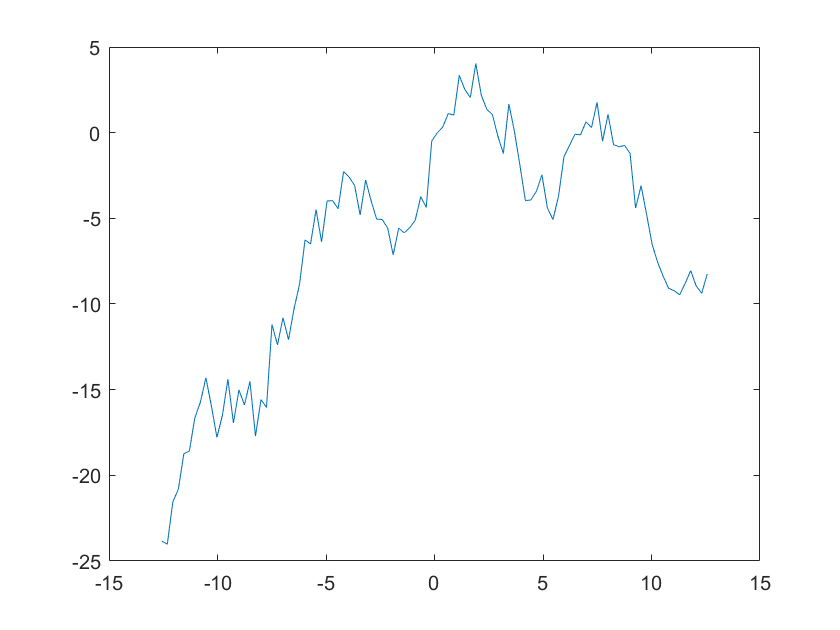

load('Exercise_Data.mat')
noise=1*randn(1,100);
x=linspace(-4*pi,4*pi,100);
y=3*sin(x)-0.1*(x-pi).^2+noise;
plot(x,y)

Eine weitere praktische ergänzung zu den Apps sind die im Live Editor verfügbaren LiveTasks. Damit können die Extrema auch auf bequeme Weise interaktiv aus dem Skript heraus bestimmt werden. Der verwendete Code ist auch direkt verfügbar.

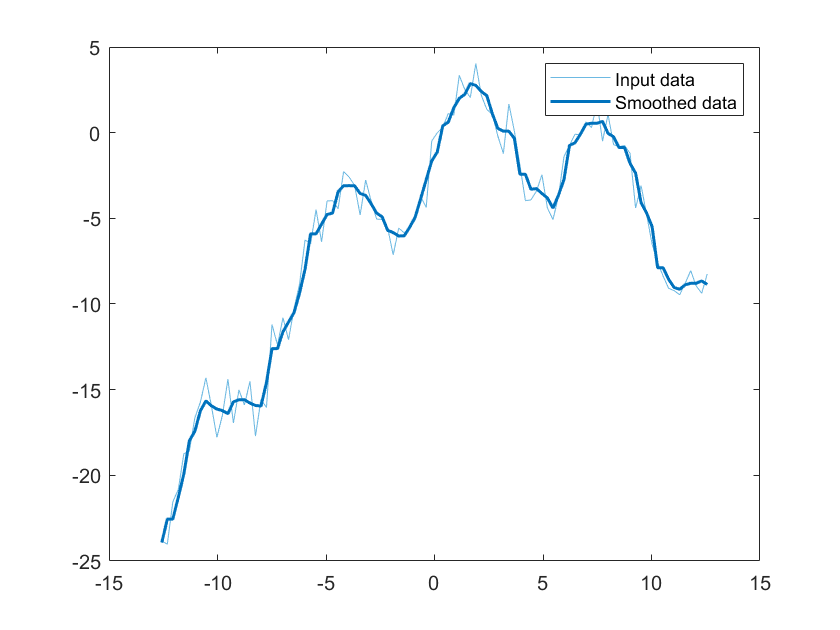

% Smooth input data
smoothedData = smoothdata(y,'movmean','SmoothingFactor',0.05,'SamplePoints',x);

% Visualize results
clf
plot(x,y,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(x,smoothedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

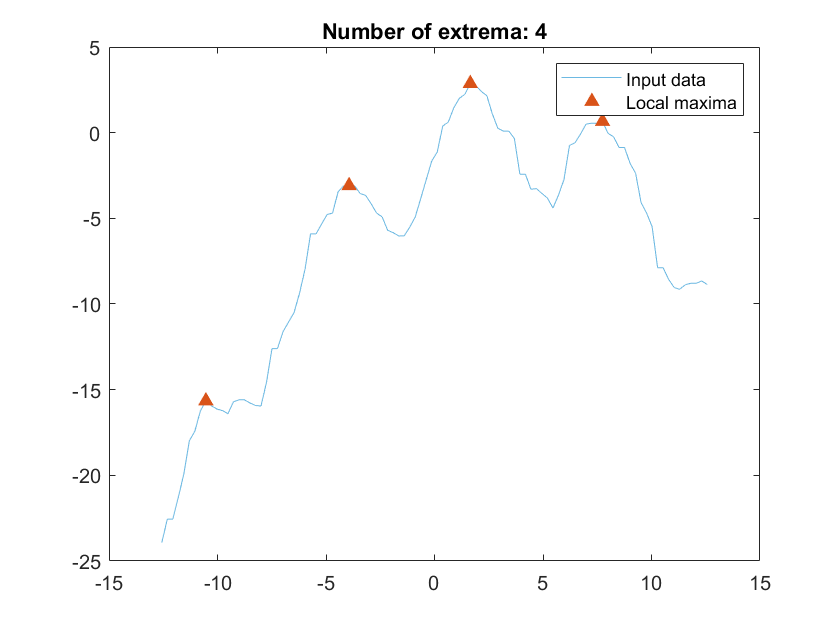

% Find local maxima
maxIndices = islocalmax(smoothedData,'MaxNumExtrema',4,'SamplePoints',x);

% Visualize results
clf
plot(x,smoothedData,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot local maxima
plot(x(maxIndices),smoothedData(maxIndices),'^','Color',[217 83 25]/255,...
    'MarkerFaceColor',[217 83 25]/255,'DisplayName','Local maxima')
title(['Number of extrema: ' num2str(nnz(maxIndices))])
hold off
legend

x(maxIndices)

ans =   -10.5354   -3.9349    1.6501    7.7429
